clear
%data_tabelle=readtable("Lebensdauer_Bueroklammer.csv");
%data=data_tabelle.Zyklen;
%data_tabelle=readtable("viskositaet.xlsx");
%data=data_tabelle.Viskositaet;

%data=randn([20,1])+4;
data=rand([20,1])+3;
a=1;
%x-Daten, Anzahl Datenwerte etc.
    anzahl=length(data);
    x=(min(data)-a:0.1:max(data)+a);

%Bei allen Optionen ist der Default-Wert das 95% Konfidenzintervall, ändern
%mit z.B. "Alpha",0.01

%Konfidenzintervalle der Parameter von Verteilungen
pd_norm=fitdist(data,"Normal")

pd_norm =   NormalDistribution

  Normal distribution
       mu =  3.58697   [3.43502, 3.73892]
    sigma = 0.324664   [0.246904, 0.474195]


ci_normal=paramci(pd_norm,"Alpha",0.05)

ci_normal =     3.4350    0.2469
    3.7389    0.4742


pd_weibull=fitdist(data,"Weibull")

pd_weibull =   WeibullDistribution

  Weibull distribution
    A = 3.72767   [3.60778, 3.85154]
    B = 14.1134   [9.84421, 20.2339]


ci_weibull=paramci(pd_weibull,"Alpha",0.05)

ci_weibull =     3.6078    9.8442
    3.8515   20.2339


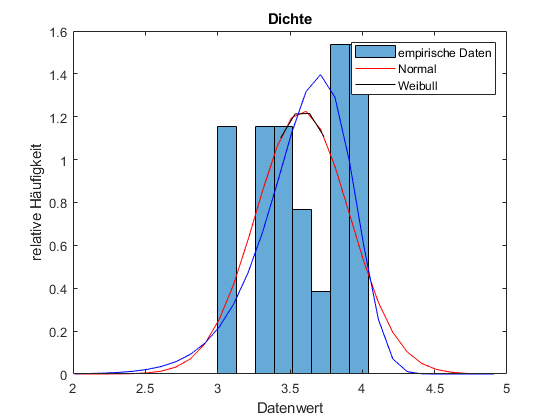


figure(1)
histogram(data,2*round(sqrt(anzahl)),'Normalization','pdf')
hold on
plot(x,normpdf(x, pd_norm.mu,pd_norm.sigma),"Color","r")
plot((ci_normal(1):0.1:ci_normal(2)),normpdf((ci_normal(1):0.1:ci_normal(2)), pd_norm.mu,pd_norm.sigma),"Color","black")
plot(x,wblpdf(x, pd_weibull.A,pd_weibull.B),"Color","b")

title('Dichte')
xlabel('Datenwert')
ylabel('relative Häufigkeit')
legend('empirische Daten', 'Normal','Weibull')
hold off

%Konfidenzintervalle über Tests
%t-Verteilung:
[~,~,t_ci,t_stats]=ttest(data)

t_ci =     3.4350
    3.7389


t_stats = struct with fields:
    tstat: 49.4093
       df: 19
       sd: 0.3247


%Verteilungsunabhängige Konfidenzintervalle für Quantile
%Berechnung des Konfidenzintervalls für den Median (McGill 1978)
ci_lower=median(data)-1.57*(quantile(data,0.75)-quantile(data,0.25))/sqrt(anzahl)

ci_lower = 3.4214

ci_upper=median(data)+1.57*(quantile(data,0.75)-quantile(data,0.25))/sqrt(anzahl)

ci_upper = 3.7690

ci_median=[ci_lower,ci_upper]

ci_median =     3.4214    3.7690


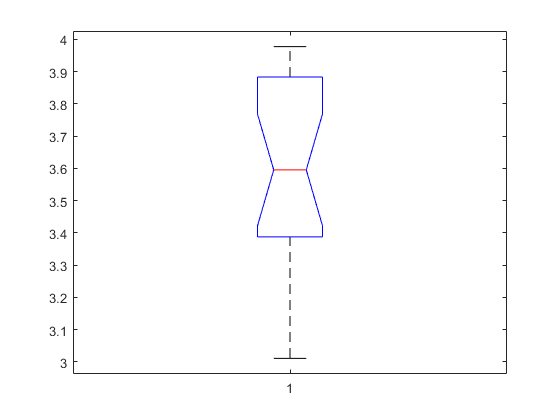


%Veranschaulichung der Verteilung incl. Konfidenzintervall vom Median im
%Boxplot (Matlab verwendet obige Formel)
boxplot(data,"Notch","on")

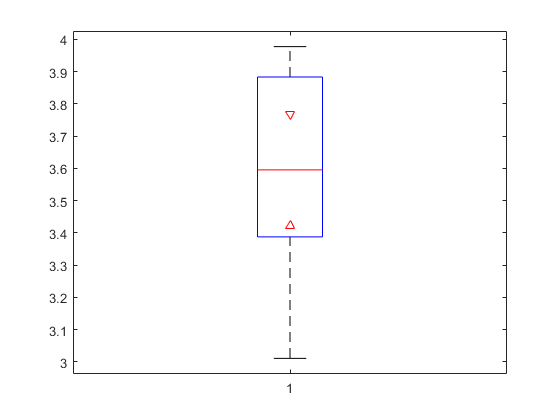

boxplot(data,"Notch","marker")

%Bootstrapping 
[boot_stats, data_boot]=bootstrp(100,@median,data)

boot_stats =     3.5745
    3.7632
    3.8205
    3.4935
    3.5952
    3.6288
    3.5516
    3.4382
    3.5142
    3.5103


data_boot =      7    12     9    20     9    19    13    13    16    13    16     8    16    10    12     5    10    18     4    20     2    13    19     8     4    10     2    19    17     4     3     3     9    12    18    19    10    12     4    14     5    13     1    20     3    18    13     3     6     6
    10     5     3    17    18     2    16    18    19    10     6     9     2     1     3     8    13     5    15     4     1     5     5    16     2    14    15     5    20     8     1    17    15     4    20    19    10    17     5    13     9    13     5     5    10     2     9    19     6     1
    10     2    12    20     5     2    13    14     8     9    11     2    20     9    20     7    12    11    14    19     1     7    10    17     2    16     9    16     4     2     9    20    20     9     1     2     2     3    12    17    16    19    19    15     6     5     3     1    14     7
    15     1     3    16    16    12    15    16     3     4     5    14    16     3 

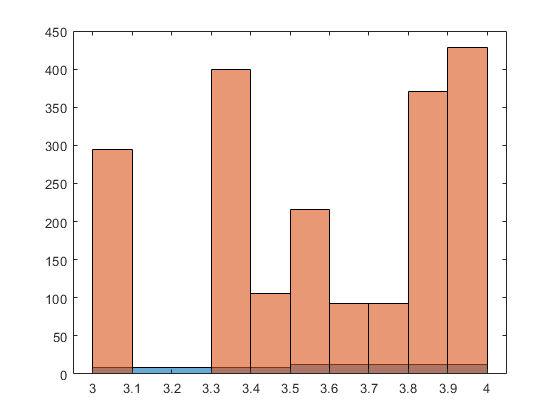

figure(4)
histogram(data)
hold on
histogram(data(data_boot))
hold off

ci_boot_mean=bootci(100,{@mean,data})

ci_boot_mean =     3.4121
    3.6790


[ci_boot_median,stats]=bootci(100,{@median,data})

ci_boot_median =     3.3997
    3.8778


stats =     3.8778
    3.4382
    3.7807
    3.5952
    3.5516
    3.6724
    3.5310
    3.4382
    3.4935
    3.4767
